# A simple reembedding demo

## with a small dataset included in the repo to display the notation and basic operations

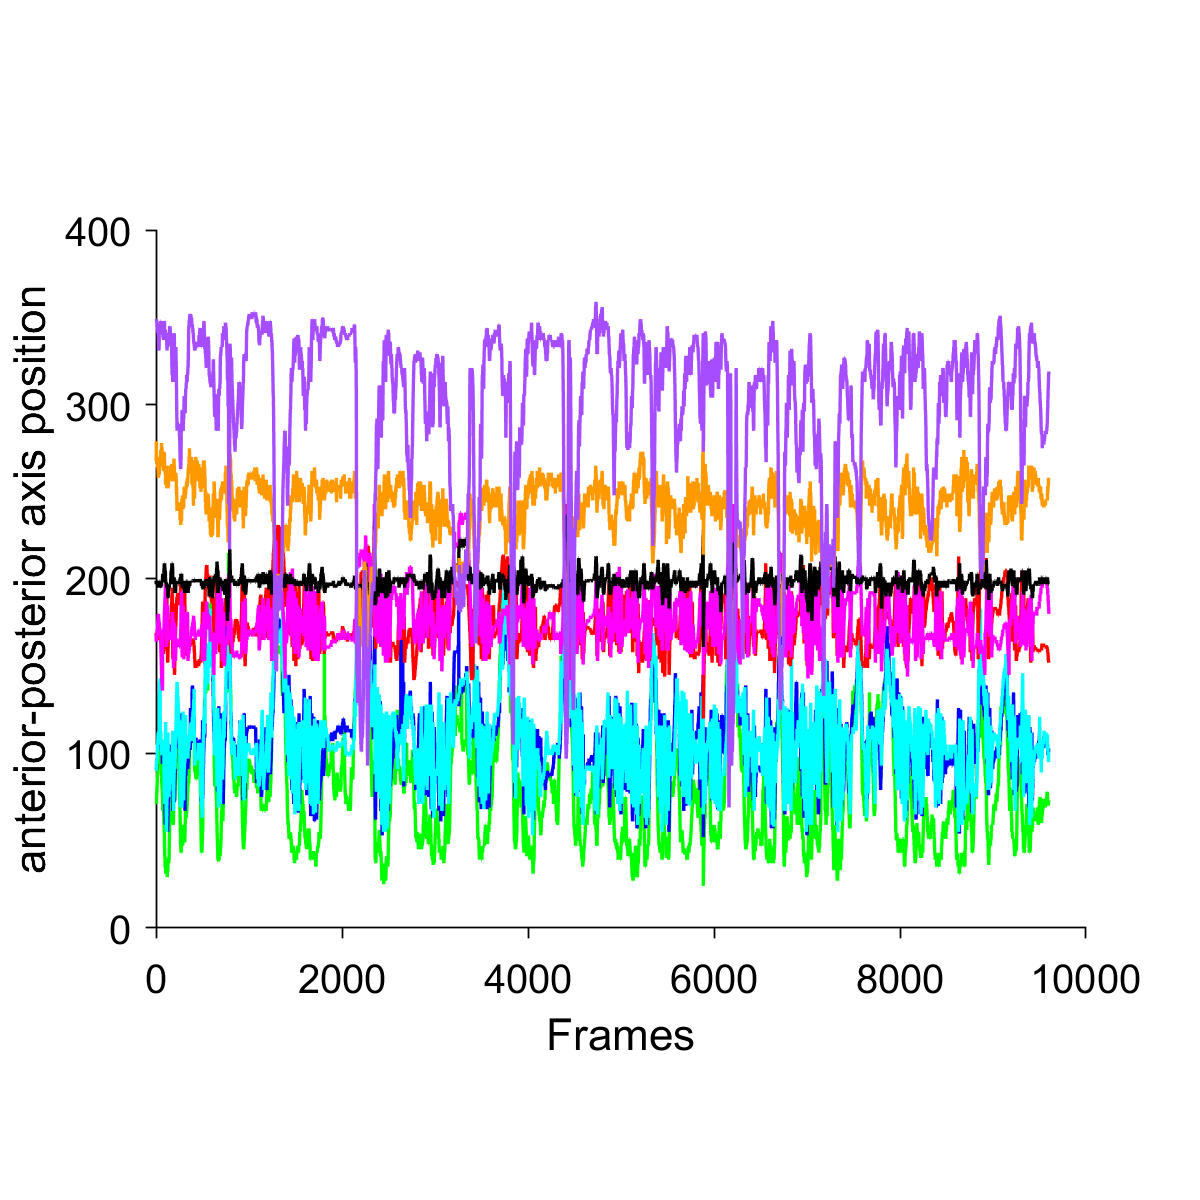

clear; gcp; % start a parallel engine

% Find base repository path (where this file is contained)
basePath = fileparts(which('demo_reembedding.mlx'));
% Add to MATLAB path
idcs   = strfind(basePath,filesep);
addpath(genpath(fullfile(basePath(1:idcs(end)-1))));

% load LEAP output and plot body parts predictions for fragment of the movie
jj=h5read("demo_MMM_LEAPpred.h5", '/positions_pred');
juse = [1 2 5 6 7 8 12 13 14 15 16];
jplot = [1 8 7 12 13 16 17 18];
idxs = 40001:49600; % frames to visualize
figure;
cj = [0 1 0; 0 0 1; 0 1 1; 1 0 0; 1 0 1; 0 0 0; 255/255 153/255 0/255; 166/255 77/255 255/255];
for i = 1:8
    plot(squeeze(jj(jplot(i),2,idxs)),'LineWidth',1,'Color',cj(i,:)); hold on
end
prepfig;
set(gca,'PlotBoxAspectRatio',[1 0.75 1]); ylabel('anterior-posterior axis position'); xlabel('Frames');

## calculate distances from body part positions

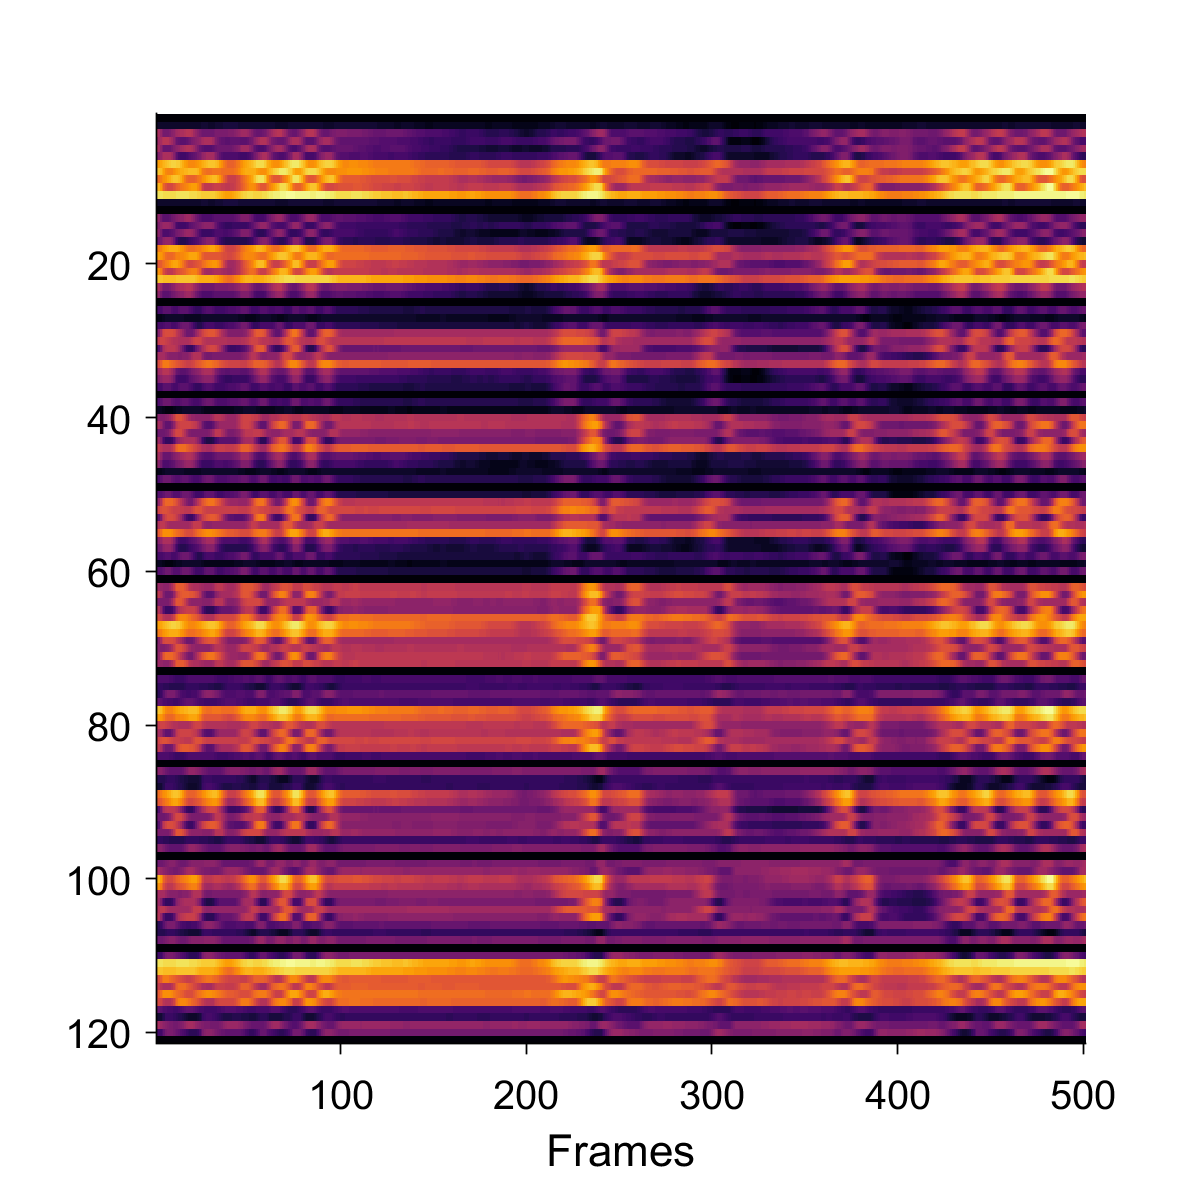

xIdx = juse;
yIdx = juse;
[X, Y] = meshgrid(xIdx,yIdx);
X = X(:); Y = Y(:);
IDX = find(X~=Y);

p1 = jj;
p1Dist = zeros(size(juse,2)*size(juse,2),size(p1,3));

for ii = 1:size(p1Dist,1)
    p1Dist(ii,:) = returnDist(squeeze(p1(X(ii),:,:)),squeeze(p1(Y(ii),:,:)));
end

p1Dsmooth = zeros(size(p1Dist));
for ii = 1:size(p1Dist,1)
    p1Dsmooth(ii,:) = medfilt1(smooth(p1Dist(ii,:),'moving',5,'omitnan'),5, 'omitnan');
end

p1Dist = p1Dsmooth;
figure;
imagesc(p1Dist(:,idxs(4500:5000)));
colormap inferno
prepfig; xlabel('Frames');

## make PCA projections of distances

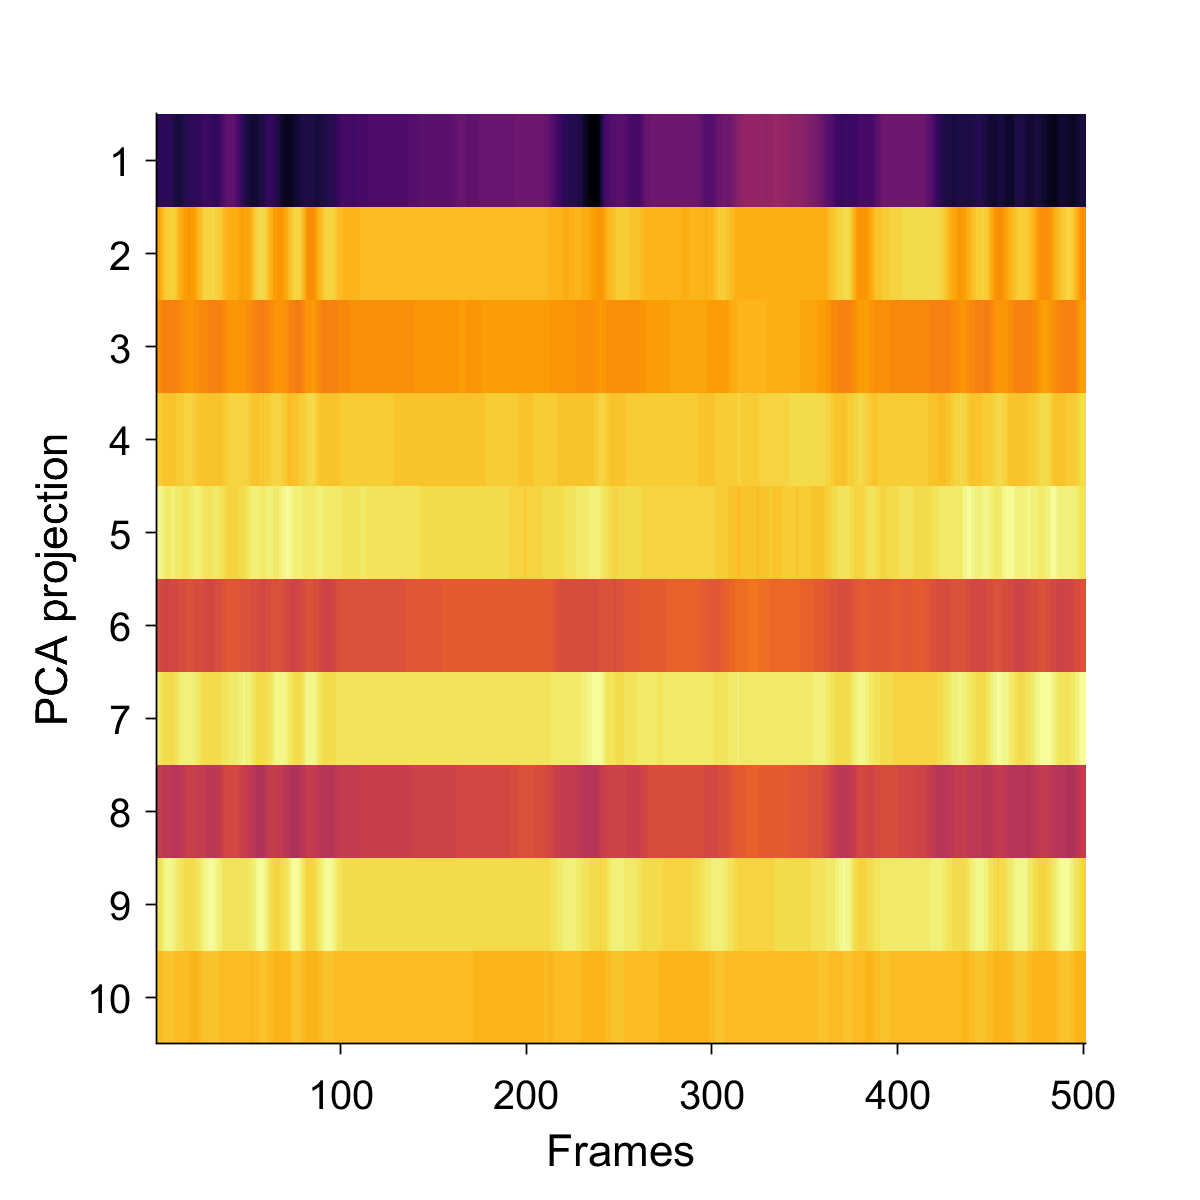

load('vecsVals_subSelect.mat')

numProjections = 10; numModes = 10; pcaModes = 10;
p2Dist = bsxfun(@minus,p1Dist(IDX,:),muv');
DistProjections = p2Dist'*vecs(:,1:numProjections);
figure;
imagesc(DistProjections(idxs(4500:5000),:)');
colormap inferno
prepfig; ylabel('PCA projection'); xlabel('Frames');

## Wavelet transform

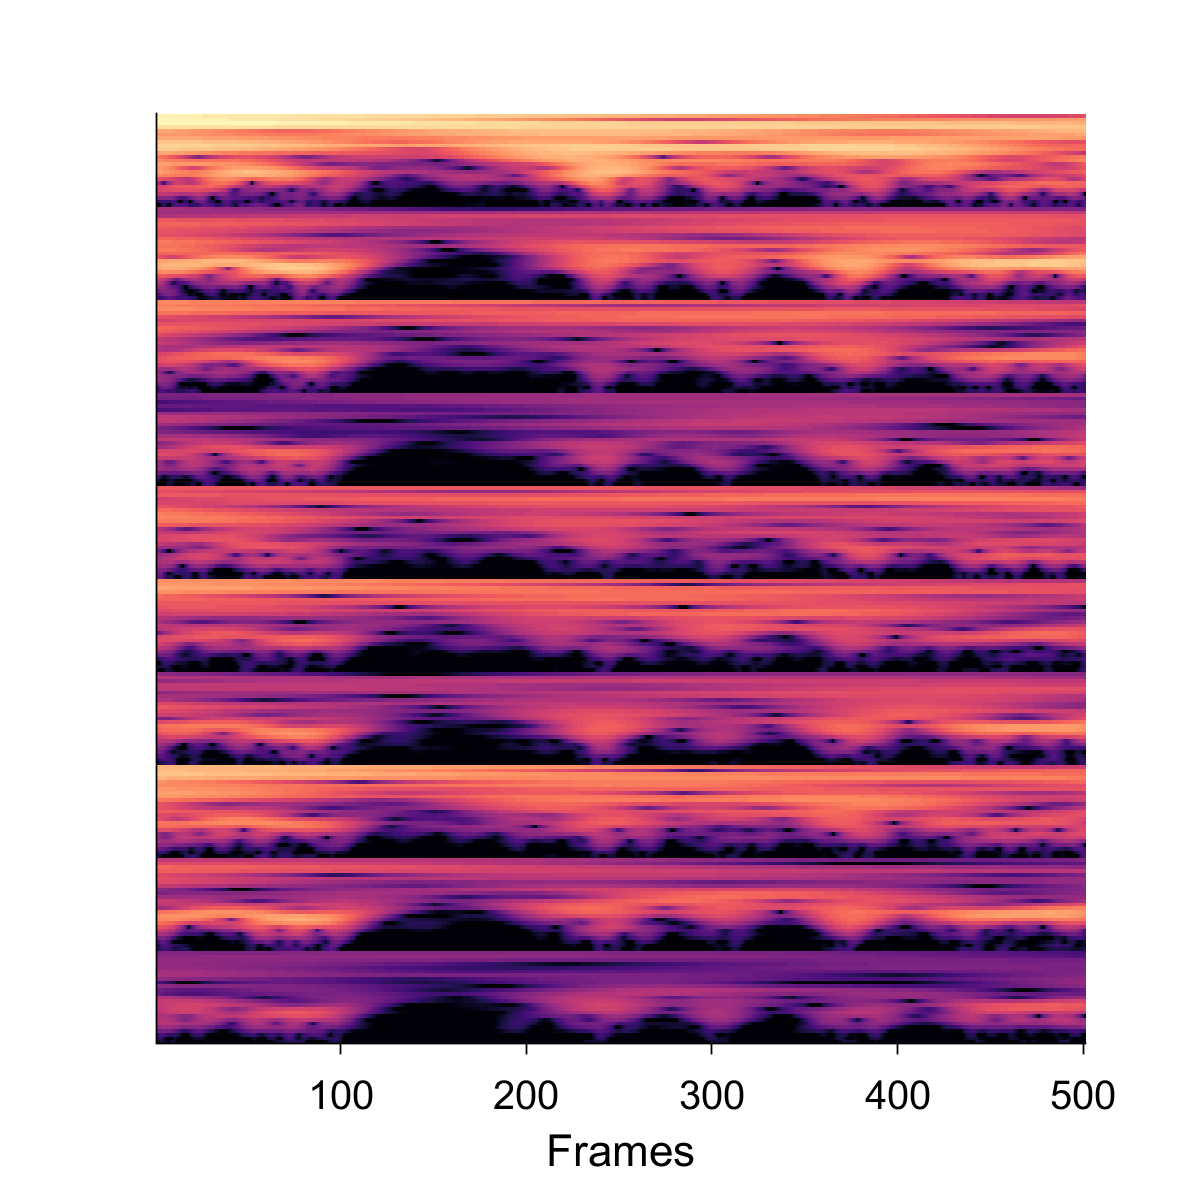

parameters = setRunParameters([]);
parameters.pcaModes = 10;
parameters.samplingFreq = 80;
parameters.minF = .25;
parameters.maxF = 20;
parameters.numModes = numModes;

[data,f] = findWavelets(DistProjections,numModes,parameters);
data = log(data); data(data<-3) = -3;
figure;
imagesc(data(idxs(4500:5000),:)');
colormap magma
prepfig; yticks([]); xlabel('Frames');

## Embedding new data to behavior space

% load training dataset
load('trainingSet_new10.mat')

trainingData = dataAll; trainingEmbedding = ydata; cdata1 = C100;

KK = 101;
[cGuesses,pClusts] = reembedHDK(DistProjections,parameters,trainingData,cdata1,KK);

	 Processing batch #   1 out of    5
Size of current Data = 20000    250
	 Processing batch #   2 out of    5
Size of current Data = 20000    250
	 Processing batch #   3 out of    5
Size of current Data = 20000    250
	 Processing batch #   4 out of    5
Size of current Data = 20000    250
	 Processing batch #   5 out of    5
Size of current Data = 15998    250


## Behavior clusters

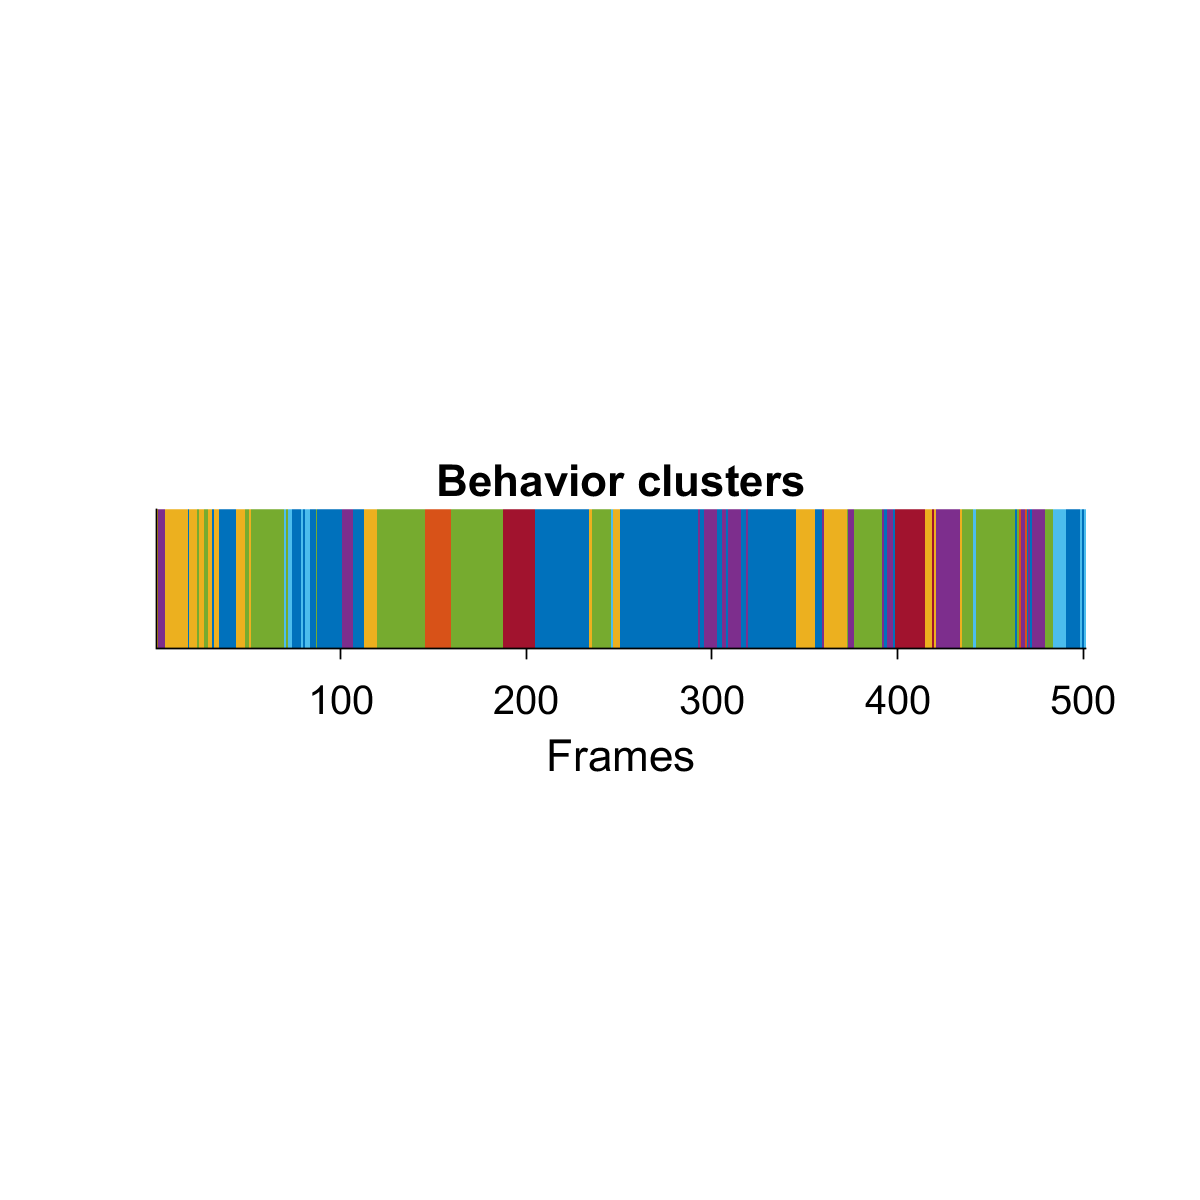

C1CON = cGuesses;
imagesc(C1CON(idxs(4500:5000),1)')
prepfig;
set(gca,'PlotBoxAspectRatio',[1 0.15 1])
colormap lines
yticks([]); xlabel('Frames');
title('Behavior clusters')

## Behavior classes

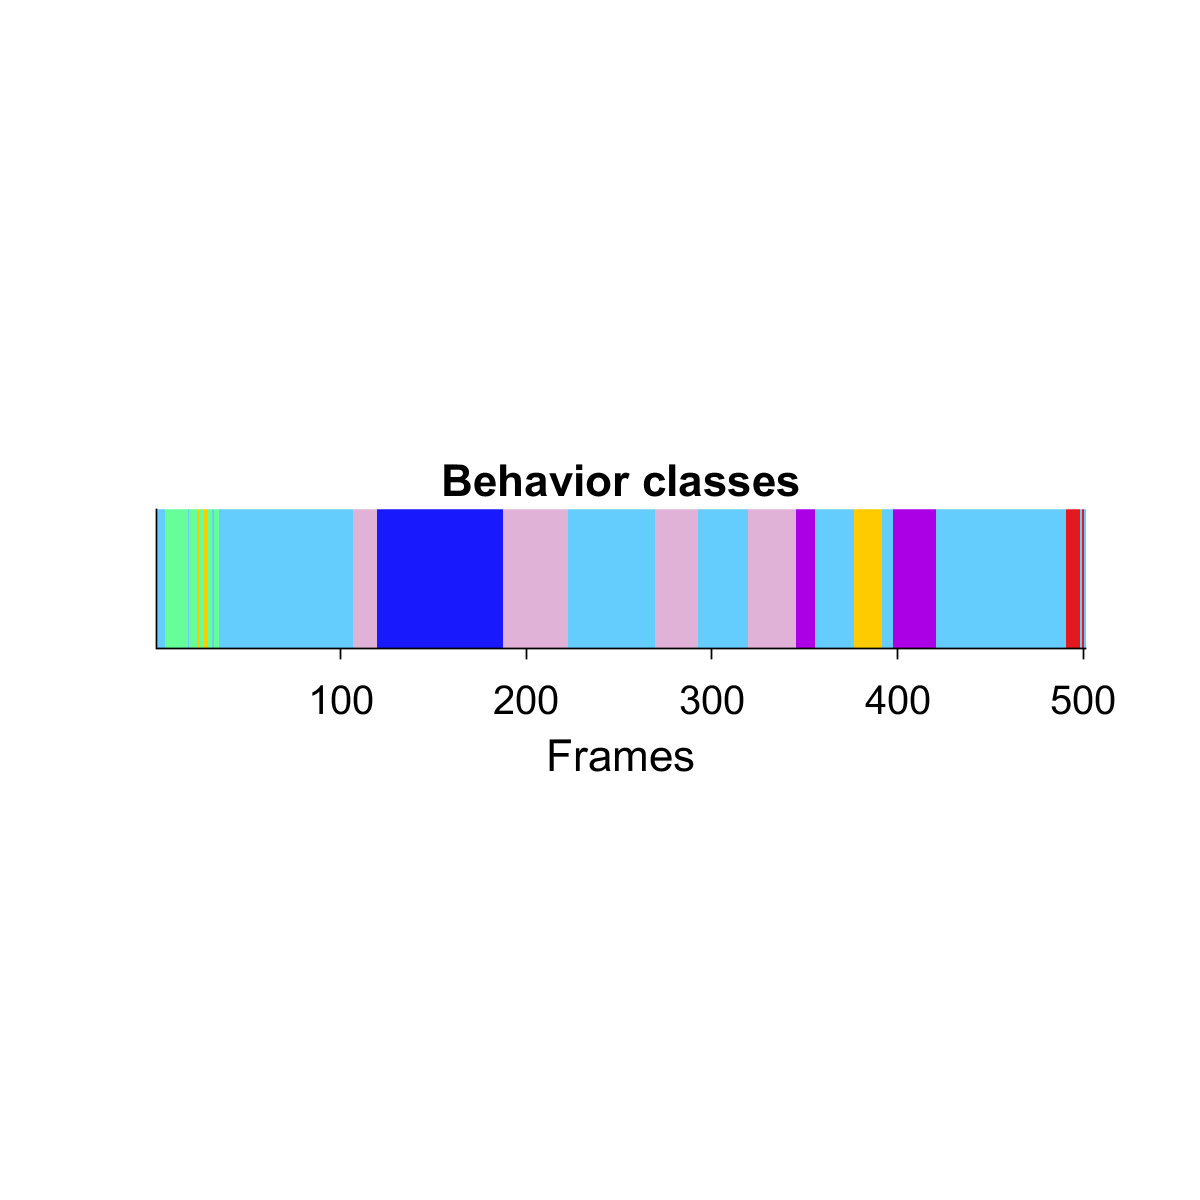

% colormap for idle, groom, slow exp, fast exp, rear, climb, turning, locomotion
cbarbeh = [26 26 255;
    102 205 255;
    225 179 217; %204 204 255;
    172 0 230; %152 78 163;
    102 255 153;
    0 204 0;
    255 204 0;
    228 26 28]./256;

% supervised sorting 
sortid8 = [3 8 2 7 5 3 2 3 6 2 4 5 6 7 2 6 2 8 8 1 1 5 8 8 8 2 6 3 4 5 3 5 2 7 5 2 7 2 5 2 6 2 8 2 4 6 8 8 7 2 3 5 1 8 7 2 8 2 8 7 2 8 8 4 2 8 4 8 6 6 5 5 5 5 8 7 5 3 6 8 3 4 4 2 4 6 2 7 8 5 4 2 8 4 8 2 3 2 2 6];

sC1CON = sortid8(C1CON(:,1))';
imagesc(sC1CON(idxs(4500:5000),1)')
prepfig;
set(gca,'PlotBoxAspectRatio',[1 0.15 1])
colormap(cbarbeh) 
yticks([]); xlabel('Frames');
title('Behavior classes')